**Title : Matlab Assignment 1 "Digital Image Processing"**

Mohsen Ahmadi  (Z23640005)

**Table of content:**

    1- Read MRI images from the directory

    2- Show images on the subplot

    3- Use the different filter for each image

    4- Show filtered images

    5- Save Images

    6- References

clear
close

**1-Read MRI images from directory**

imds = imageDatastore({'1.png','2.png','3.png','4.png'});
img1 = readimage(imds,1);
img2 = readimage(imds,2);
img3 = readimage(imds,3);
img4 = readimage(imds,4);

**2- Show images on subplot**

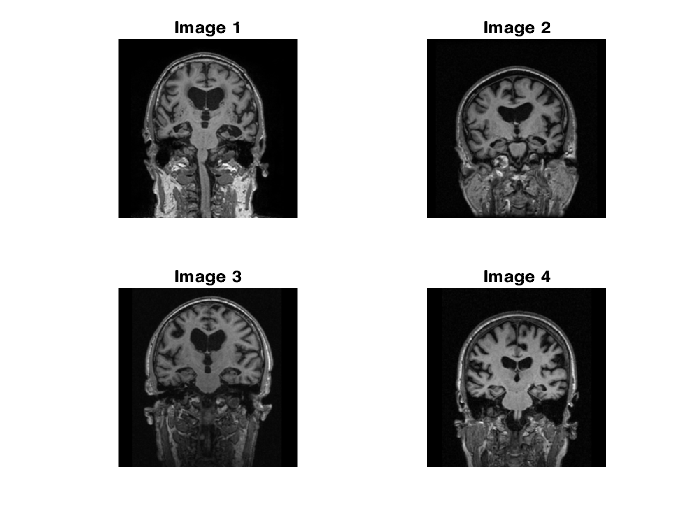

subplot(2,2,1); 
imshow(img1)
title('Image 1')
subplot(2,2,2); 
imshow(img2)
title('Image 2')
subplot(2,2,3); 
imshow(img3)
title('Image 3')
subplot(2,2,4); 
imshow(img4)
title('Image 4')

**3- Use different filter for each image**

Image 1 :Inverted using Dehazing Algorithm

Image 2:Reduce the haze using the imreducehaze function

Image 3:Histogram equalization

Image 4:Contrast-limited adaptive histogram equalization

image1_Invert = imcomplement(img1);
image2_Invert = imreducehaze(img2);
image3_Invert = histeq(img3);
image4_Invert = adapthisteq(img4);

**4- Show filtered images**

F=figure;
subplot(2,2,1); 
imshow(image1_Invert)
title('Image 1:Inverted imge');
subplot(2,2,2); 
imshow(image2_Invert)
title('Image 2:Reduce the haze')
subplot(2,2,3); 
imshow(image3_Invert)
title('Image 3:Histogram equalization')
subplot(2,2,4); 
imshow(image4_Invert)
title('Image 4:Adaptive histogram')

**5- Save images**

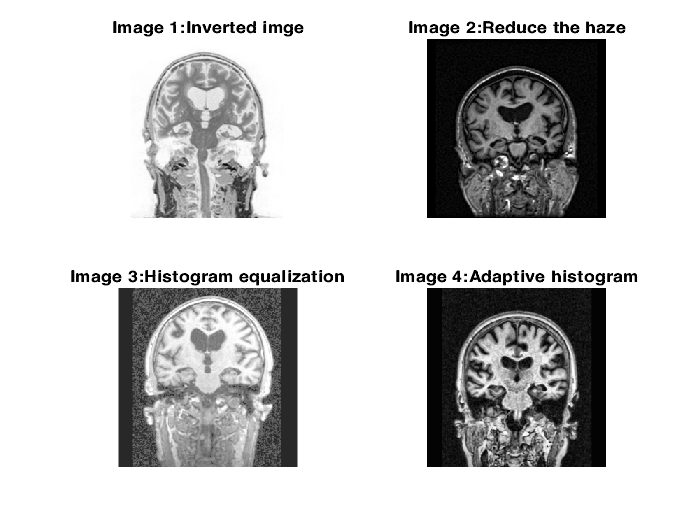

saveas(F,'result.png');

**6- References:**

1-  [https://www.mathworks.com/](https://www.mathworks.com/)

2-  [https://www.kaggle.com](https://www.kaggle.com)